# SNW_VFI_PARAM Tiny Solution Analysis Consumption Rule Changes

**back to **[**Fan**](https://fanwangecon.github.io)**'s **[**Intro Math for Econ**](https://fanwangecon.github.io/Math4Econ/)**,  **[**Matlab Examples**](https://fanwangecon.github.io/M4Econ/)**, or **[**Dynamic Asset**](https://fanwangecon.github.io/CodeDynaAsset/)** Repositories**

This is the example vignette for function: [**snw_vfi_main**](https://github.com/FanWangEcon/PrjOptiSNW/tree/master/PrjOptiSNW/params/snw_vfi_main.m) from the [**PrjOptiSNW Package**](https://fanwangecon.github.io/PrjOptiSNW/)**. **This function analyzes the effects of the consumption allocation rule on model choices. The consumption allocation rule could be such that been married and having children does not change contemperaneous utility, only changes income. 

- Household consumption is within household public good. Having children and been married only impacts income

- Marginal utility of household consumption is higher when there are more kids and given marriage with uniform division of consumption for each household member, and the household planner cares about household consumption divided by the number of individuals in the household

- Consumption divide by square root of household member count. 

## Public Good: Test SNW_VFI_MAIN Tiny with cons_allocation_rule = 0 

Call the function with defaults.

mp_param = snw_mp_param('default_tiny');
mp_param('cons_allocation_rule') = 0

mp_param =   Map with properties:

        Count: 29
      KeyType: char
    ValueType: any


[V_VFI_car0,ap_VFI_car0,cons_VFI_car0,exitflag_VFI_car0] = snw_vfi_main(mp_param);

SNW_VFI_MAIN: Finished Age Group:7 of 7
SNW_VFI_MAIN: Finished Age Group:6 of 7
SNW_VFI_MAIN: Finished Age Group:5 of 7
SNW_VFI_MAIN: Finished Age Group:4 of 7
SNW_VFI_MAIN: Finished Age Group:3 of 7
SNW_VFI_MAIN: Finished Age Group:2 of 7
SNW_VFI_MAIN: Finished Age Group:1 of 7
Elapsed time is 83.892532 seconds.
Completed SNW_VFI_MAIN;SNW_MP_PARAM=;default_tiny;SNW_MP_CONTROL=;default_base


## Tiny Param Results Define Frames

Define the matrix dimensions names and dimension vector values. Policy and Value Functions share the same ND dimensional structure.

% Grids:
age_grid = [19, 28:16:92, 100];
agrid = mp_param('agrid')';
eta_grid = mp_param('eta_grid')';
edu_grid = [0,1];
marry_grid = [0,1];
kids_grid = (1:1:mp_param('n_kidsgrid'))';
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
cl_mp_datasetdesc = {};
cl_mp_datasetdesc{1} = containers.Map({'name', 'labval'}, {'age', age_grid});
cl_mp_datasetdesc{2} = containers.Map({'name', 'labval'}, {'savings', agrid});
cl_mp_datasetdesc{3} = containers.Map({'name', 'labval'}, {'shock', eta_grid});
cl_mp_datasetdesc{4} = containers.Map({'name', 'labval'}, {'edu', edu_grid});
cl_mp_datasetdesc{5} = containers.Map({'name', 'labval'}, {'marry', marry_grid});
cl_mp_datasetdesc{6} = containers.Map({'name', 'labval'}, {'kids', kids_grid});

## Analyze Savings and Shocks

First, analyze Savings Levels and Shocks, Aggregate Over All Others, and do various other calculations.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
mp_support_graph('cl_st_xtitle') = {'Savings States, a'};
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = true; % do not log
mp_support_graph('st_rowvar_name') = 'z=';
mp_support_graph('it_legend_select') = 3; % how many shock legends to show
mp_support_graph('st_rounding') = '6.2f'; % format shock legend

#### MEAN(VAL(A,Z)), MEAN(AP(A,Z)), MEAN(C(A,Z))

Tabulate value and policies along savings and shocks:

% Set
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [1,4,5,6,3,2];
% Value Function
tb_az_v = ff_summ_nd_array("MEAN(VAL(A,Z))", V_VFI_car0, true, ["mean"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(VAL(A,Z))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group         savings         mean_shock__0_72413    mean_shock__0_36206      mean_shock_0       mean_shock_0_36206    mean_shock_0_72413 
    _____    _________________    ___________________    ___________________    _________________    __________________    ___________________

      1                      0     -3.00621299958408      -2.41688074313862     -1.95185271854418     -1.61363148198852      -1.34390242700751
      2      0.260631001371742    -0.990540067063672     -0.738555294159451     -0.51272990856691    -0.306192345561178    -0.0959828129430132
      3       2.08504801097394     0.889862621525114      0.927186897740453     0.969903958773551      1.01683629109758       1.066070243804

% Aprime Choice
tb_az_ap = ff_summ_nd_array("MEAN(AP(A,Z))", ap_VFI_car0, true, ["mean"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(AP(A,Z))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group         savings         mean_shock__0_72413    mean_shock__0_36206       mean_shock_0       mean_shock_0_36206    mean_shock_0_72413
    _____    _________________    ___________________    ___________________    __________________    __________________    __________________

      1                      0     0.019548399575183      0.043771667301537     0.0620498801863466    0.0817056275390892    0.209993163377407 
      2      0.260631001371742     0.145174757262008      0.149380278452984      0.156052565671041     0.230097673482499    0.388988848206388 
      3       2.08504801097394      1.45859074753736       1.45859074806908        1.4585907464181       1.4585907481382     1.45859074728014

% Consumption Choices
tb_az_c = ff_summ_nd_array("MEAN(C(A,Z))", cons_VFI_car0, true, ["mean"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(C(A,Z))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group         savings         mean_shock__0_72413    mean_shock__0_36206      mean_shock_0       mean_shock_0_36206    mean_shock_0_72413
    _____    _________________    ___________________    ___________________    _________________    __________________    __________________

      1                      0     0.361899255607005      0.434467744301748     0.552859078530504    0.726950129741156       0.8742901655757 
      2      0.260631001371742     0.675906776806092      0.767319342709572     0.896323809992846     1.01523906006023      1.13139056563426 
      3       2.08504801097394      2.39480368844769       2.48820465664047      2.62166339119441     2.81254736665818      3.08577612239578 
    

Graph Mean Values:

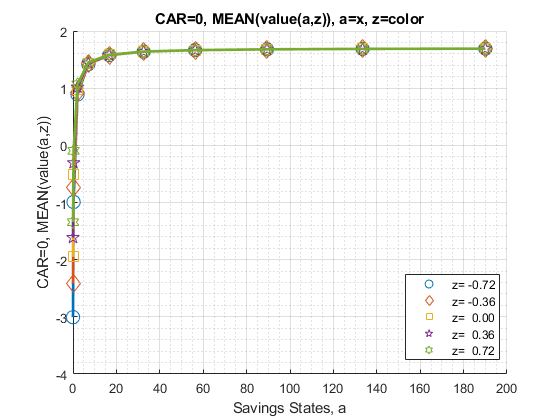

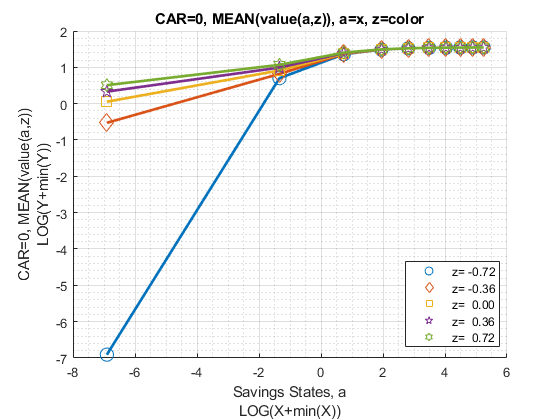

mp_support_graph('cl_st_graph_title') = {'CAR=0, MEAN(value(a,z)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'CAR=0, MEAN(value(a,z))'};
ff_graph_grid((tb_az_v{1:end, 3:end})', eta_grid, agrid, mp_support_graph);

Graph Mean Savings Choices:

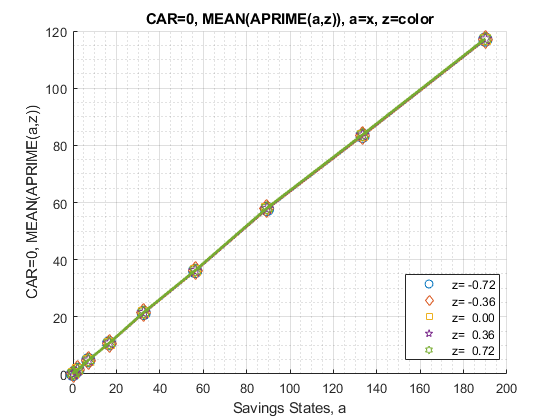

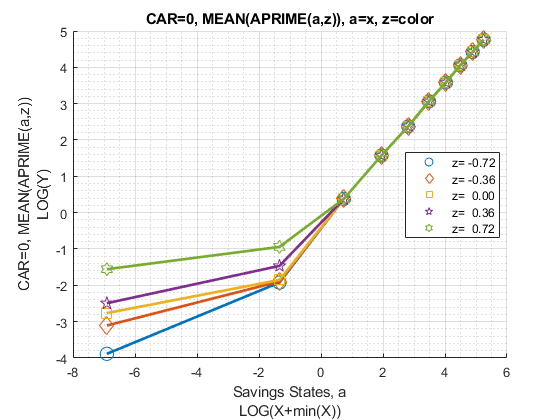

mp_support_graph('cl_st_graph_title') = {'CAR=0, MEAN(APRIME(a,z)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'CAR=0, MEAN(APRIME(a,z))'};
ff_graph_grid((tb_az_ap{1:end, 3:end})', eta_grid, agrid, mp_support_graph);

Graph Mean Consumption:

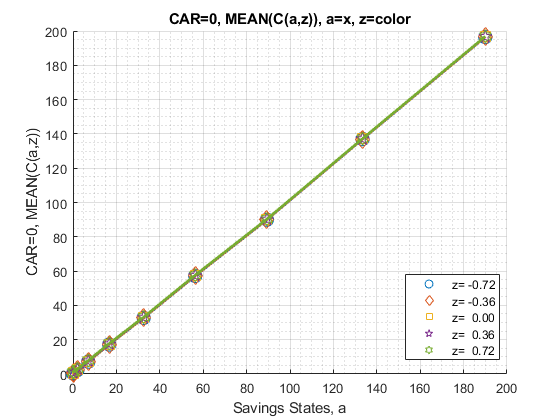

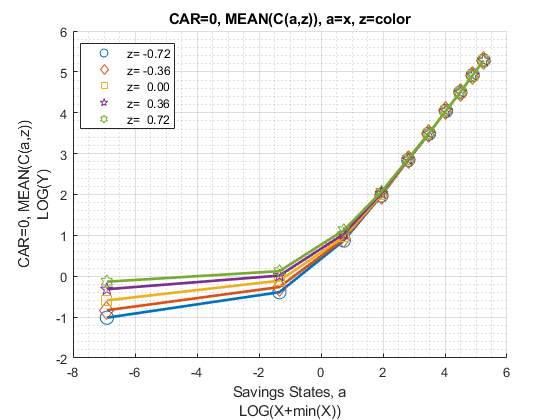

mp_support_graph('cl_st_graph_title') = {'CAR=0, MEAN(C(a,z)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'CAR=0, MEAN(C(a,z))'};
ff_graph_grid((tb_az_c{1:end, 3:end})', eta_grid, agrid, mp_support_graph);

## Analyze Kids and Marriage and Age

Aggregating over education, savings, and shocks, what are the differential effects of Marriage and Age.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
ar_row_grid = ["k0M0", "K1M0", "K2M0", "k0M1", "K1M1", "K2M1"];
mp_support_graph('cl_st_xtitle') = {'Age'};
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = true; % do not log
mp_support_graph('st_rounding') = '6.2f'; % format shock legend
mp_support_graph('cl_scatter_shapes') = { 'o', 'd' ,'s', 'o', 'd', 's'};
mp_support_graph('cl_colors') = {'red', 'red', 'red', 'blue', 'blue', 'blue'};

#### MEAN(VAL(KM,J)), MEAN(AP(KM,J)), MEAN(C(KM,J))

Tabulate value and policies along savings and shocks:

% Set
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [2,3,4,1,6,5];
% Value Function
tb_az_v = ff_summ_nd_array("MEAN(VAL(KM,J))", round(V_VFI_car0,4), true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(VAL(KM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    mean_age_19    mean_age_28    mean_age_44    mean_age_60    mean_age_76    mean_age_92    mean_age_100
    _____    ____    _____    ___________    ___________    ___________    ___________    ___________    ___________    ____________

      1       1        0       1.522117       1.502834        1.34814       1.020414        0.37415        0.37213        0.378585  
      2       2        0       1.522117       1.502834        1.34814       1.020414        0.37415        0.37213        0.378585  
      3       3        0       1.522117       1.502834        1.34814       1

% Aprime Choice
tb_az_ap = ff_summ_nd_array("MEAN(AP(KM,J))", ap_VFI_car0, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(AP(KM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry      mean_age_19         mean_age_28         mean_age_44         mean_age_60         mean_age_76         mean_age_92       mean_age_100
    _____    ____    _____    ________________    ________________    ________________    ________________    ________________    ________________    ____________

      1       1        0      52.7680077568699    52.7800680727241    50.5013882042961    39.5241438132213    29.4197382841121    8.44444443213358         0      
      2       2        0      52.7680077554601    52.7800680392535     50.501385729774    39.5241538190468    29.41977127

% Consumption Choices
tb_az_c = ff_summ_nd_array("MEAN(C(KM,J))", cons_VFI_car0, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(C(KM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry      mean_age_19         mean_age_28         mean_age_44         mean_age_60         mean_age_76         mean_age_92         mean_age_100  
    _____    ____    _____    ________________    ________________    ________________    ________________    ________________    ________________    ________________

      1       1        0      34.8469388870054    35.0776922931398    37.6164571700509    48.5594689287935    57.8346726499529    78.8099665019315     87.254410934065
      2       2        0      34.8469388884153    35.0776923266103     37.616459644573     48.559458922968    

Graph Mean Values:

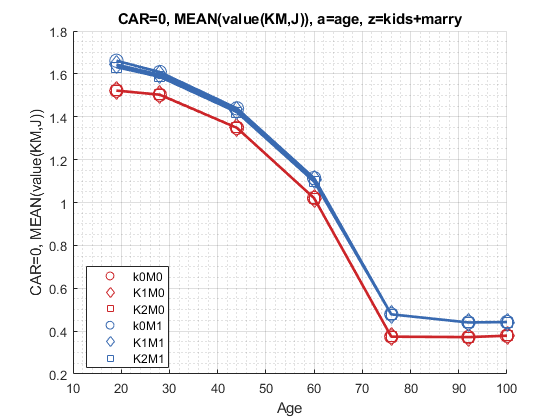

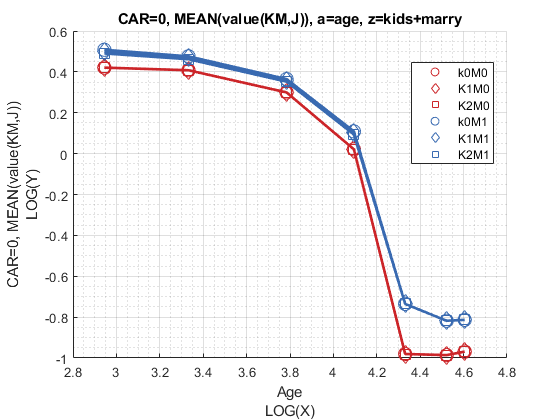

mp_support_graph('cl_st_graph_title') = {'CAR=0, MEAN(value(KM,J)), a=age, z=kids+marry'};
mp_support_graph('cl_st_ytitle') = {'CAR=0, MEAN(value(KM,J))'};
ff_graph_grid((tb_az_v{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Savings Choices:

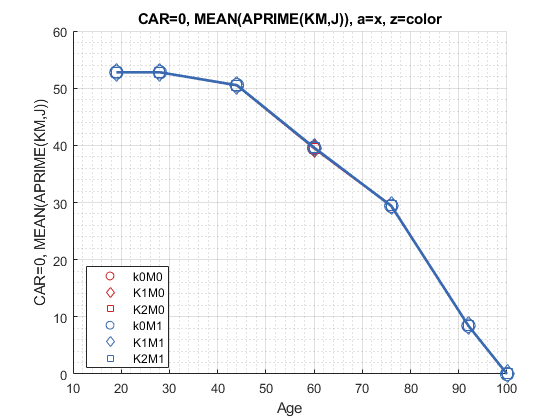

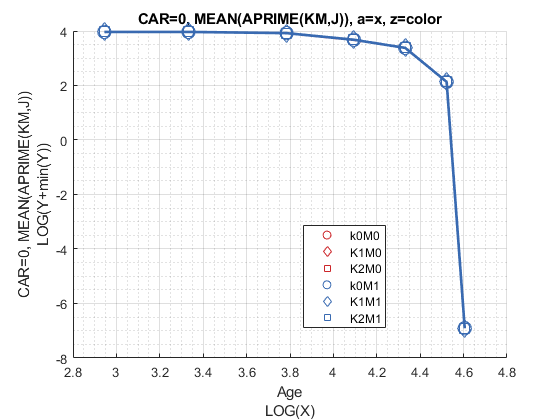

mp_support_graph('cl_st_graph_title') = {'CAR=0, MEAN(APRIME(KM,J)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'CAR=0, MEAN(APRIME(KM,J))'};
ff_graph_grid((tb_az_ap{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Consumption:

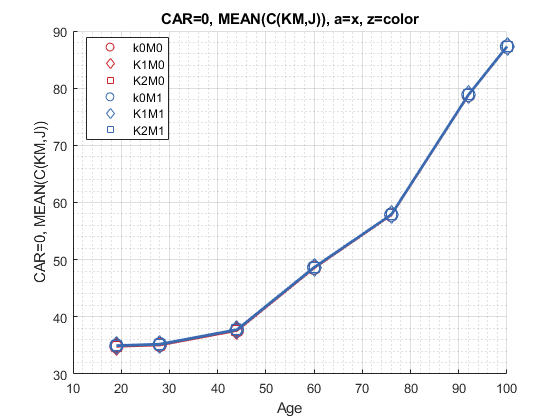

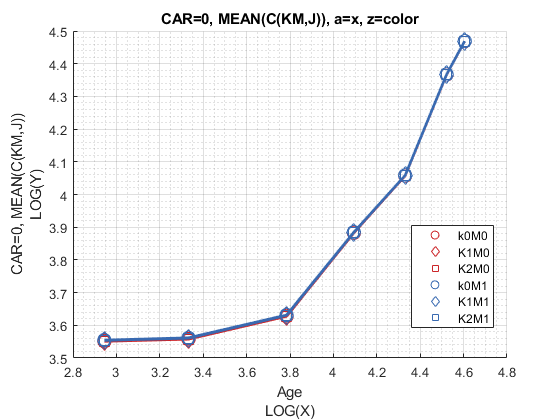

mp_support_graph('cl_st_graph_title') = {'CAR=0, MEAN(C(KM,J)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'CAR=0, MEAN(C(KM,J))'};
ff_graph_grid((tb_az_c{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

## Analyze Education and Marriage and Age

Aggregating over education, savings, and shocks, what are the differential effects of Marriage and Age.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
ar_row_grid = ["E0M0", "E1M0", "E0M1", "E1M1"];
mp_support_graph('cl_st_xtitle') = {'Age'};
mp_support_graph('st_legend_loc') = 'eastoutside';
mp_support_graph('bl_graph_logy') = true; % do not log
mp_support_graph('st_rounding') = '6.2f'; % format shock legend
mp_support_graph('cl_scatter_shapes') = {'*', 'p', '*','p' };
mp_support_graph('cl_colors') = {'red', 'red', 'blue', 'blue'};

#### MEAN(VAL(EKM,J)), MEAN(AP(EKM,J)), MEAN(C(EKM,J))

Tabulate value and policies:

% Set
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [2,3,6,1,4,5];
% Value Function
tb_az_v = ff_summ_nd_array("MEAN(VAL(EKM,J))", V_VFI_car0, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(VAL(EKM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    edu    marry      mean_age_19         mean_age_28         mean_age_44          mean_age_60          mean_age_76          mean_age_92         mean_age_100   
    _____    ___    _____    ________________    ________________    ________________    _________________    _________________    _________________    _________________

      1       0       0      1.46968779673247    1.42543058301238    1.27092301437184    0.951167112970747    0.311232487550004    0.329842828545558    0.337916702749494
      2       1       0      1.57453620133413    1.58024125896008      1.425352537504     1.089658

% Aprime Choice
tb_az_ap = ff_summ_nd_array("MEAN(AP(EKM,J))", ap_VFI_car0, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(AP(EKM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    edu    marry      mean_age_19         mean_age_28         mean_age_44         mean_age_60         mean_age_76         mean_age_92       mean_age_100
    _____    ___    _____    ________________    ________________    ________________    ________________    ________________    ________________    ____________

      1       0       0      52.7765014764421    52.7801217166117    50.4610320268222    39.4349394604757    29.4294446120291    8.44444442891845         0      
      2       1       0      52.7595140361987    52.7800143738486    50.5417454246063    39.6133516388321    29.41005444771

% Consumption Choices
tb_az_c = ff_summ_nd_array("MEAN(C(EKM,J))", cons_VFI_car0, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(C(EKM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    edu    marry      mean_age_19         mean_age_28         mean_age_44         mean_age_60         mean_age_76         mean_age_92         mean_age_100  
    _____    ___    _____    ________________    ________________    ________________    ________________    ________________    ________________    ________________

      1       0       0      34.8384451674333    34.9787486581871    37.4741840056983    48.4833348377399     57.806722534622    78.7917227177326    87.2361671466511
      2       1       0      34.8554326076767    35.1766359830805    37.7587292915672     48.635599546982    57.

Graph Mean Values:

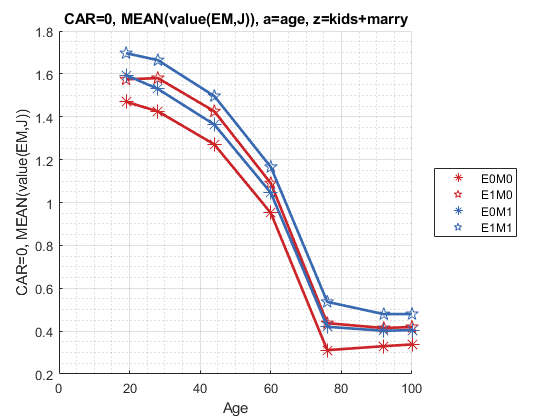

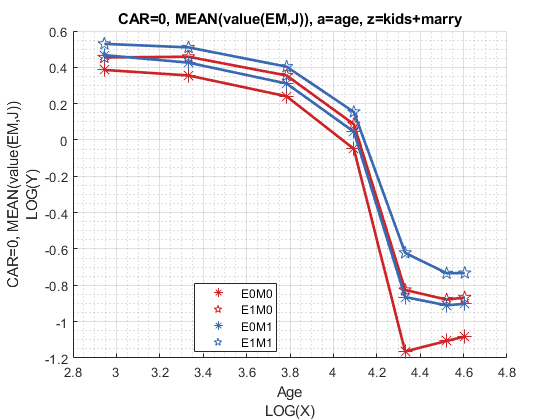

mp_support_graph('cl_st_graph_title') = {'CAR=0, MEAN(value(EM,J)), a=age, z=kids+marry'};
mp_support_graph('cl_st_ytitle') = {'CAR=0, MEAN(value(EM,J))'};
ff_graph_grid((tb_az_v{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Savings Choices:

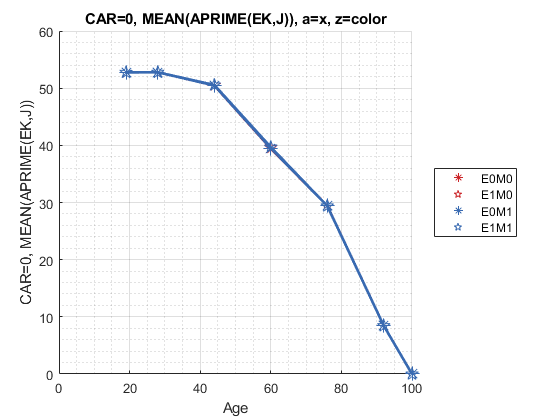

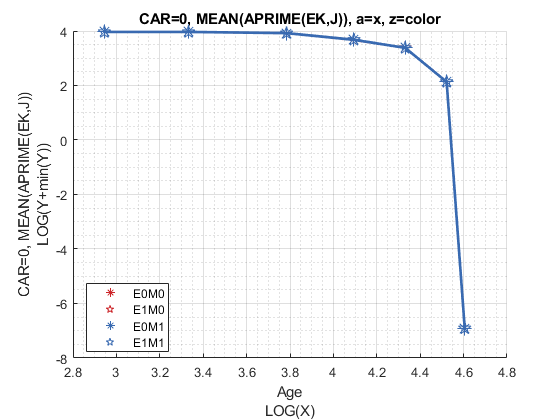

mp_support_graph('cl_st_graph_title') = {'CAR=0, MEAN(APRIME(EK,J)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'CAR=0, MEAN(APRIME(EK,J))'};
ff_graph_grid((tb_az_ap{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Consumption:

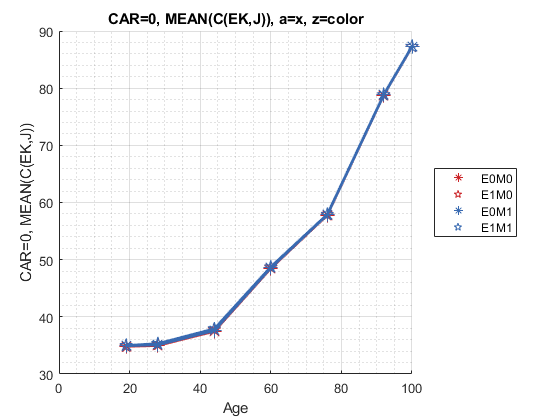

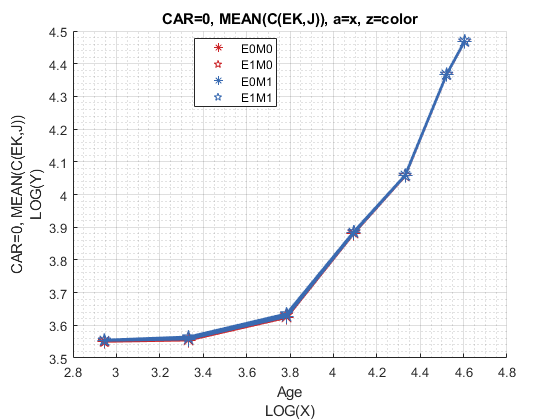

mp_support_graph('cl_st_graph_title') = {'CAR=0, MEAN(C(EK,J)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'CAR=0, MEAN(C(EK,J))'};
ff_graph_grid((tb_az_c{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);